# Count particles in each cell

Import image files and ROIs; image size is 512x512 px

clear;clc

%     foldername = 'D:\Dropbox\000a Data transfer\TCRb internalization\220319'; % copy-and-pasete     
%     input_filename_ori='4_62';  % file name
%     input_filename_ori='5_63';  % file name  
%     input_filename_ori = '6_63'; % file name  

%     foldername = 'D:\Dropbox\000a Data transfer\TCRb internalization\220318'; % copy-and-pasete     
%     input_filename_ori='4_56';  % file name
%     input_filename_ori='5_57';  % file name  
%     input_filename_ori = '6_57'; % file name  

%     foldername = 'D:\Dropbox\000a Data transfer\TCRb internalization\220313'; % copy-and-pasete     
%     input_filename_ori='4_50';  % file name
%     input_filename_ori='5_58';  % file name  
%     input_filename_ori = '6_50';
    
%     foldername = 'D:\Dropbox\000a Data transfer\TCRb internalization\210708'; % copy-and-pasete     
%     input_filename_ori='4_37';  % file name
%     input_filename_ori='5_27';  % file name  
%     input_filename_ori = '6_41';    

    foldername = 'D:\Dropbox\000a Data transfer\TCRb internalization\210710'; % copy-and-pasete     
%     input_filename_ori='7_51';  % file name
%     input_filename_ori='8_43';  % file name  
    input_filename_ori = '9_55';    

Generate file names

    input_filename=[input_filename_ori, '_TCR_max.tif']; % image name
    cstrFilenames = [input_filename_ori, '_RoiSet.zip'];  % Cellpose boundary data
    cstrtext=[input_filename_ori, '_particle.csv'];  % ROI info
    celltext=[input_filename_ori, '_cell.xlsx'];  % Output
    
    scale = 0.4143; % micron/px
    
    foldername = [foldername, '\']; 
    input_filename = [foldername, input_filename];  
    cstrFilenames = [foldername, cstrFilenames];  
    cstrtext = [foldername, cstrtext];  
    celltext = [foldername, celltext];
    
    preimage(:,:,1)= imread(input_filename, 1);  % import tif image
   

Center cooridnates of particle (Pl) , data from threshold pixels 

    T=readtable(cstrtext);
    area = str2double(T.Area(1:end));
    Particle = [T.X(1:end), T.Y(1:end)];  % center of praticle
    Particle = Particle./scale; % micron to px
    Particle = round(Particle);
    Pl_map = zeros(size(preimage,1), size(preimage,2)); 
    
    % set 1 to the central position of ROI
    for m=1:size(Particle,1)
        Pl_map(Particle(m,2)+1, Particle(m,1)+1)=1;  % image j starts from zero. y, x, order
    end

Count particle in each cell, cell boundary determined by Cellpoase

    [sROI] = ReadImageJROI(cstrFilenames);    % ROI
    num_ROI = length(sROI);  
    xy = cell(1,num_ROI);  % empty cell  
    num_Pl = zeros(num_ROI,1);  
    
    
for ii=1:num_ROI
    if or(strcmp(sROI{1, ii}.strType,'Traced'), strcmp(sROI{1, ii}.strType,'Polygon'))
        xy{ii}=sROI{1,ii}.mnCoordinates;  % import coordinates of the boundary of each ROI
        cc=xy{1,ii};  
        cc(cc<0)=0;  % expand ROI make minus values
        cc(cc>511)=511;
        x=cc(:,1)+1; y=cc(:,2)+1;  % Image J starts from zero.
    
        % roipoly; Specify polygonal region of interest (ROI)
        BW = roipoly(preimage,x,y);  % logical, within ROI defined by x y coordiates
        BW = BW.*Pl_map;  % find the center of ROI within the cell of interest.
        num_Pl(ii)=sum(BW,'all');  % number of particles found each cell
                       
    else
    end
end

    writematrix(num_Pl, celltext)

Pie graph

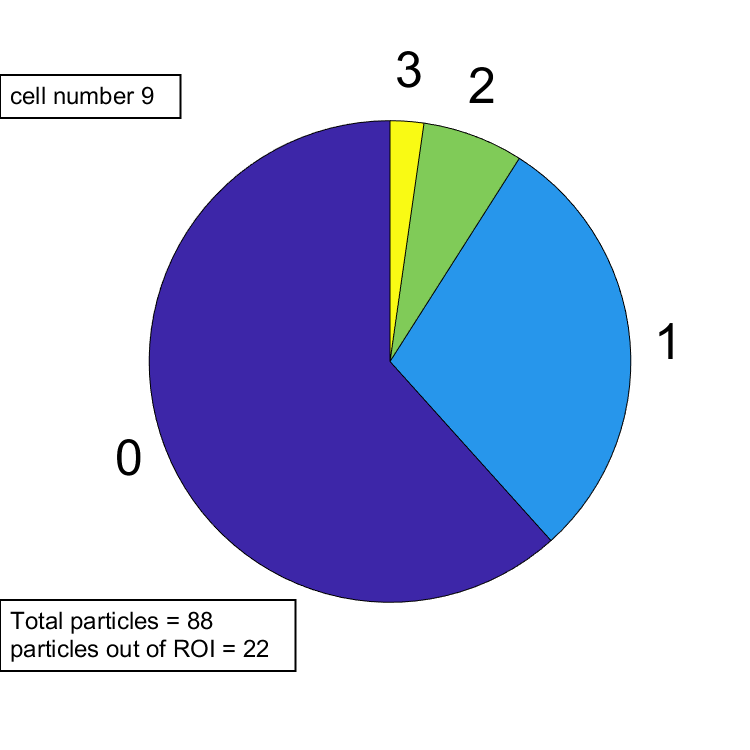

    clf
%     fprintf('Total particles');     
%     length(Particle)
%     fprintf('particles out of ROI');    
%     length(Particle)-sum(num_Pl,'all')
    
    Pl_max = max(num_Pl);  % max particle number/cell
    pie_data = zeros(Pl_max+1,1);
    
    for n=1:Pl_max+1
        pie_data(n)=length(find(num_Pl==n-1));
    end

    figure
    Pl_str = num2str((0:Pl_max)');
    f = pie(pie_data, Pl_str);  % pie graph
    dest = num2str(input_filename_ori); 
    dest = ['cell number ', dest(1:1)];
    t= annotation('textbox', [0 .1 .7 .8], 'String', dest, 'FitBoxToText',"on");
    t.FontSize = 12;
    
    str = {['Total particles = ', num2str(length(Particle))], ...
        ['particles out of ROI = ', num2str(length(Particle)-sum(num_Pl,'all'))]};
    a = annotation('textbox', [0 .1 0 .1], 'String', str, 'FitBoxToText',"on");
    a.FontSize = 12;